## Bzによるモード計算用コード(微分信号)

## get vaccum TF only shot


% z t r
% TF 4kV
date = 230119;
shot_num = 2;
low_n_folder = strcat('C:\Users\uswk0\OneDrive\ドキュメント\GitHub\test-open\道家\卒論\data\',num2str(date),'/');

% 生信号読み込み
raw_signal = read_datafile(shot_num,low_n_folder);

% もろもろの係数よみこみ
calib_coefficient = zeros(1,24);
 % probe positionによるベクトル方向
direction = ...
   [1,1,1,1,1,1,...
    -1,1,1,-1,1,1,...
    1,1,1,-1,1,1,...
    1,1,1,1,1,1];
for i = 1:8
    calib_coefficient((i-1)*3+1:(i-1)*3+3) = [37.7,41.6,133]*10^-6;
end

% 生信号を微分信号に変換
% rearrange to 1-24 in channel number according to labels on cable
dBdt_TF_only(:,1:24) = raw_signal(:,2:25)./calib_coefficient.*direction;

% 時間列
%toroidal_mode_B = toroidal_mode_raw(:,2:25)*1000;
time_array = raw_signal(:,1);

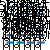

% check all V signals 
% raw signal [mV]
for i = 1:24
    subplot(6,4,i)
    plot(time_array, raw_signal(:,i+1)*10^3);
    %xlabel('us');
    %ylabel('mV')
    ylim([-50 50]);
    component_all = ['r','z','t'];
    component = component_all(rem(i,3)+1);
    title([num2str(i),'(',component,')'])
end


%ここで変数クリアしているので注意
clearvars -except dBdt_TF_only time_array date shot_num t_start t_end...
    y_upperlim y_lowerlim calib_coefficient B_TF_only low_n_folder raw_signal direction

% plotting setting
t_start = 0;
t_end = 1000;

y_upperlim = 400;
y_lowerlim = -400;

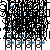

% check all dB/dt signals 
% raw signal [mV]
for i = 1:24
    subplot(6,4,i)
    hold off
    plot(time_array, dBdt_TF_only(:,i));
    %xlabel('us');
    %ylabel('mV')
    %ylim([-50 50]);
    component_all = ['r','z','t'];
    component = component_all(rem(i,3)+1);
    title([num2str(i),'(',component,')'])
    
end

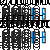

% TFのdBz/dt信号
for i = 1:8
    index_bz = i*3-2;
    subplot(2,4,i)
    plot(time_array,smooth(dBdt_TF_only(:,index_bz)));
    ylim([-400 400]);
    title(['dBz/dt from ch',num2str(index_bz)])
end
hold off

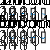

% TFのB信号(数値積分) 
dt = 10^-7;
B_TF_only = zeros(length(time_array),24);

for i = 1:24
    B_TF_only(:,i) = cumtrapz(dBdt_TF_only(:,i)*dt); 

    
end

% Bzのみプロット
% [mT]
% Bzがφだけz軸から傾いている場合,TF真空放電
% (Bz) toroidal_mode_B(:,i*3-1) = real_Bt*sin(phi)

% Bt_vacuum ~= Bt_plasma

% vaccum_TF_onlyのBzを保存

Bz_TF_only = zeros(length(time_array),8);
for i = 1:8
    index_bz = i*3-2;

    Bz_TF_only(:,i) = B_TF_only(:,index_bz);
  
    subplot(2,4,i)
  
    plot(time_array,Bz_TF_only(:,i));
   
    ylim([-0.1 0.11]);
    title(['Bz from ch',num2str(index_bz)])
   
end

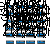


%%%%%%%%%%%　Bz_TF_only をノーマルショットから差し引く　%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% z t r
% plasmaあり　TF4kV PF39kV　shotの取得
date = 230119;
shot_num = 5;
raw_signal = read_datafile(shot_num,low_n_folder);
% rearrange to 1-24 in channel number according to labels on cable
dBdt = raw_signal(:,2:25)./calib_coefficient.*direction;
% 微分信号のプロット
plot_all_ch(time_array,dBdt,t_start, t_end,y_lowerlim, y_upperlim,0.004);

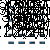

dt = 10^-7;
% 数値積分　B プロット
B = zeros(length(time_array),24);

for i = 1:24
    B(:,i) = cumtrapz(dBdt(:,i)*dt);
end
plot_all_ch(time_array,B,t_start, t_end,y_lowerlim, y_upperlim,0.004);

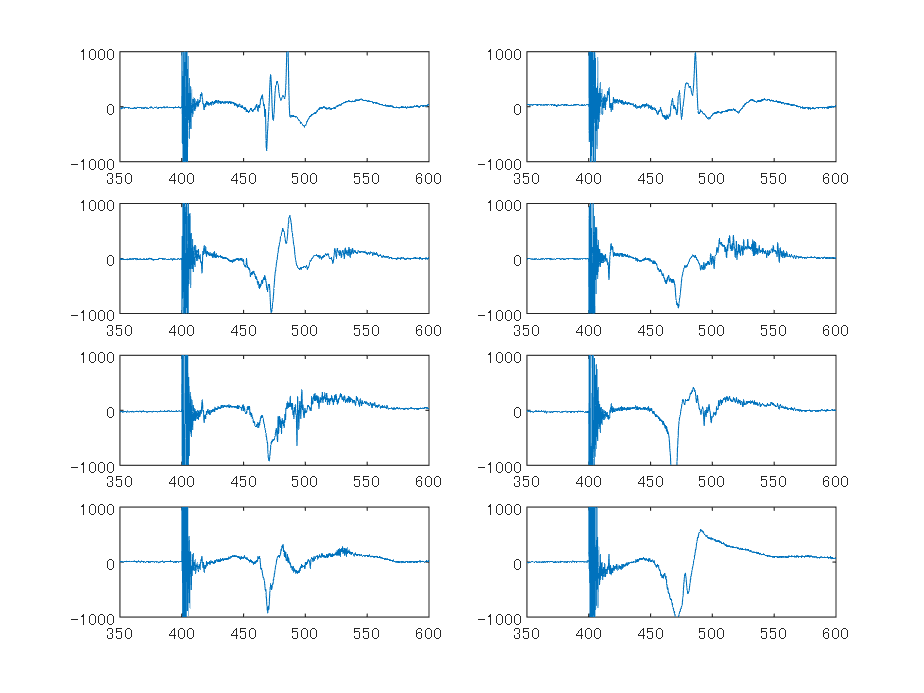

% dBz/dt生信号のみ保存&プロット
dBzdt = zeros(length(time_array), 8);
for i = 1:8
    index_bz = i*3-2;
    dBzdt(:,i) = dBdt(:,index_bz);
    subplot(4,2,i)
    hold off
    plot(time_array, smooth(dBzdt(:,i)))
    xlim([350 600])
    ylim([-1000 1000])
    
end

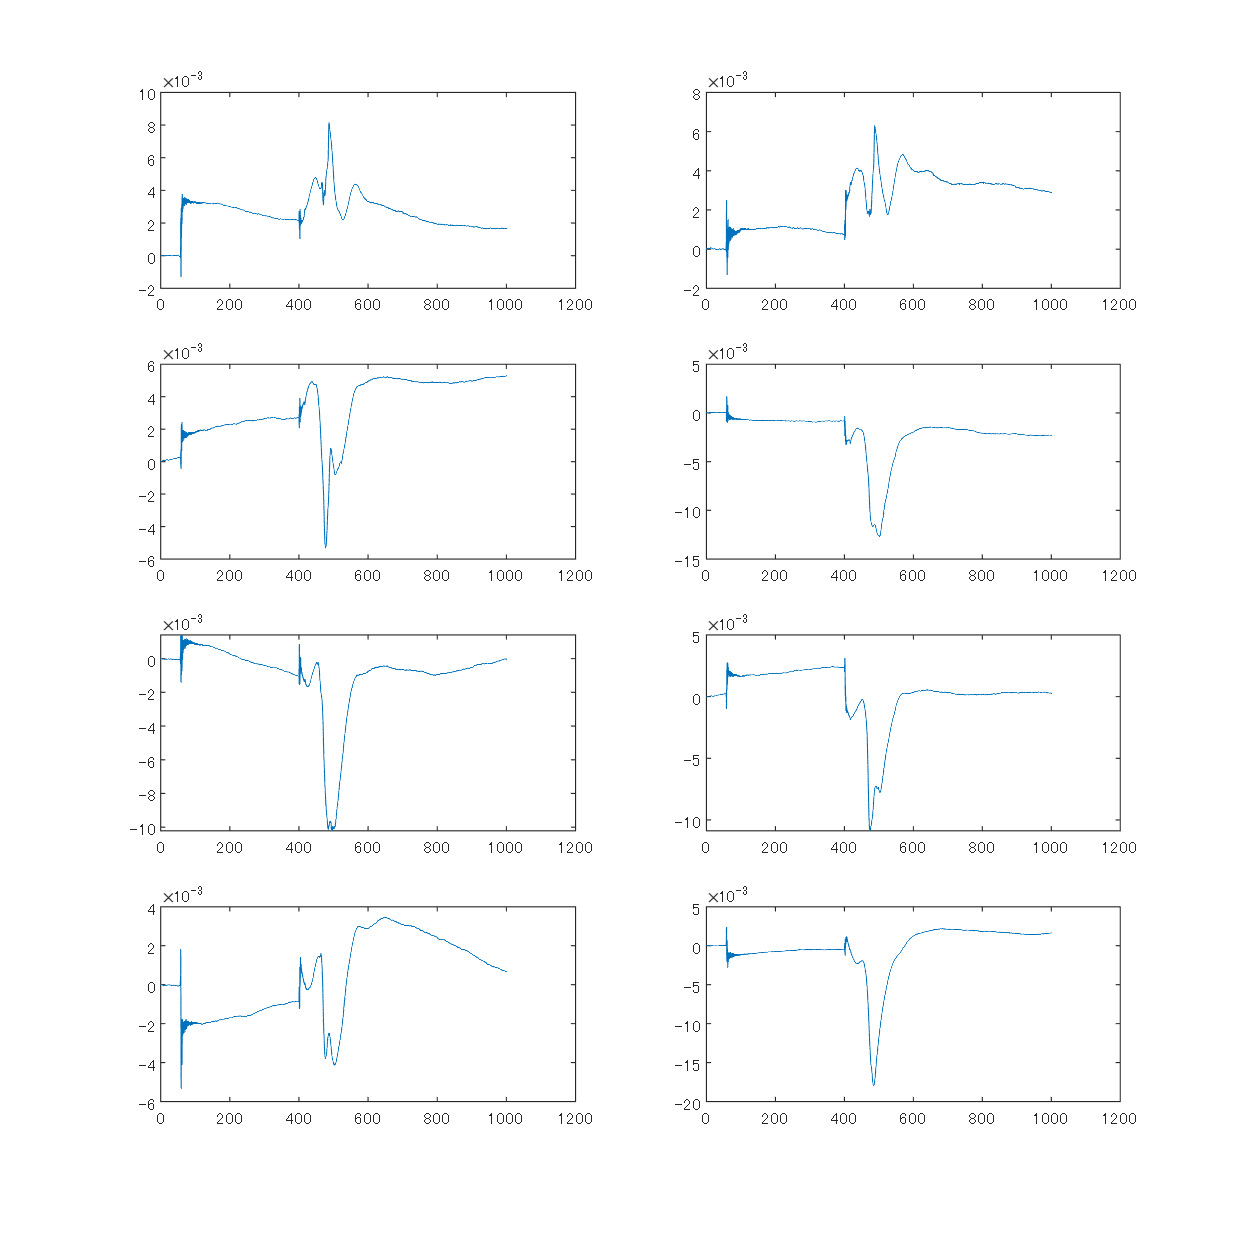

%　Bz_TF_only をBから差し引く
%%%%%%%% Bz_TF_onlyを差し引いたものを取得　%%%%%%%%%%
% 数値積分Bz

dt = 10^-7;
Bz = zeros(length(time_array),8);
for i = 1:8
    index_bz = i*3-2;
    % 数値積分
   
    
    % 差し引く
    Bz(:,i) = B(:,index_bz) - Bz_TF_only(:,i);

    subplot(4,2,i)
    plot(time_array, Bz(:,i))
end

clearvars Bz

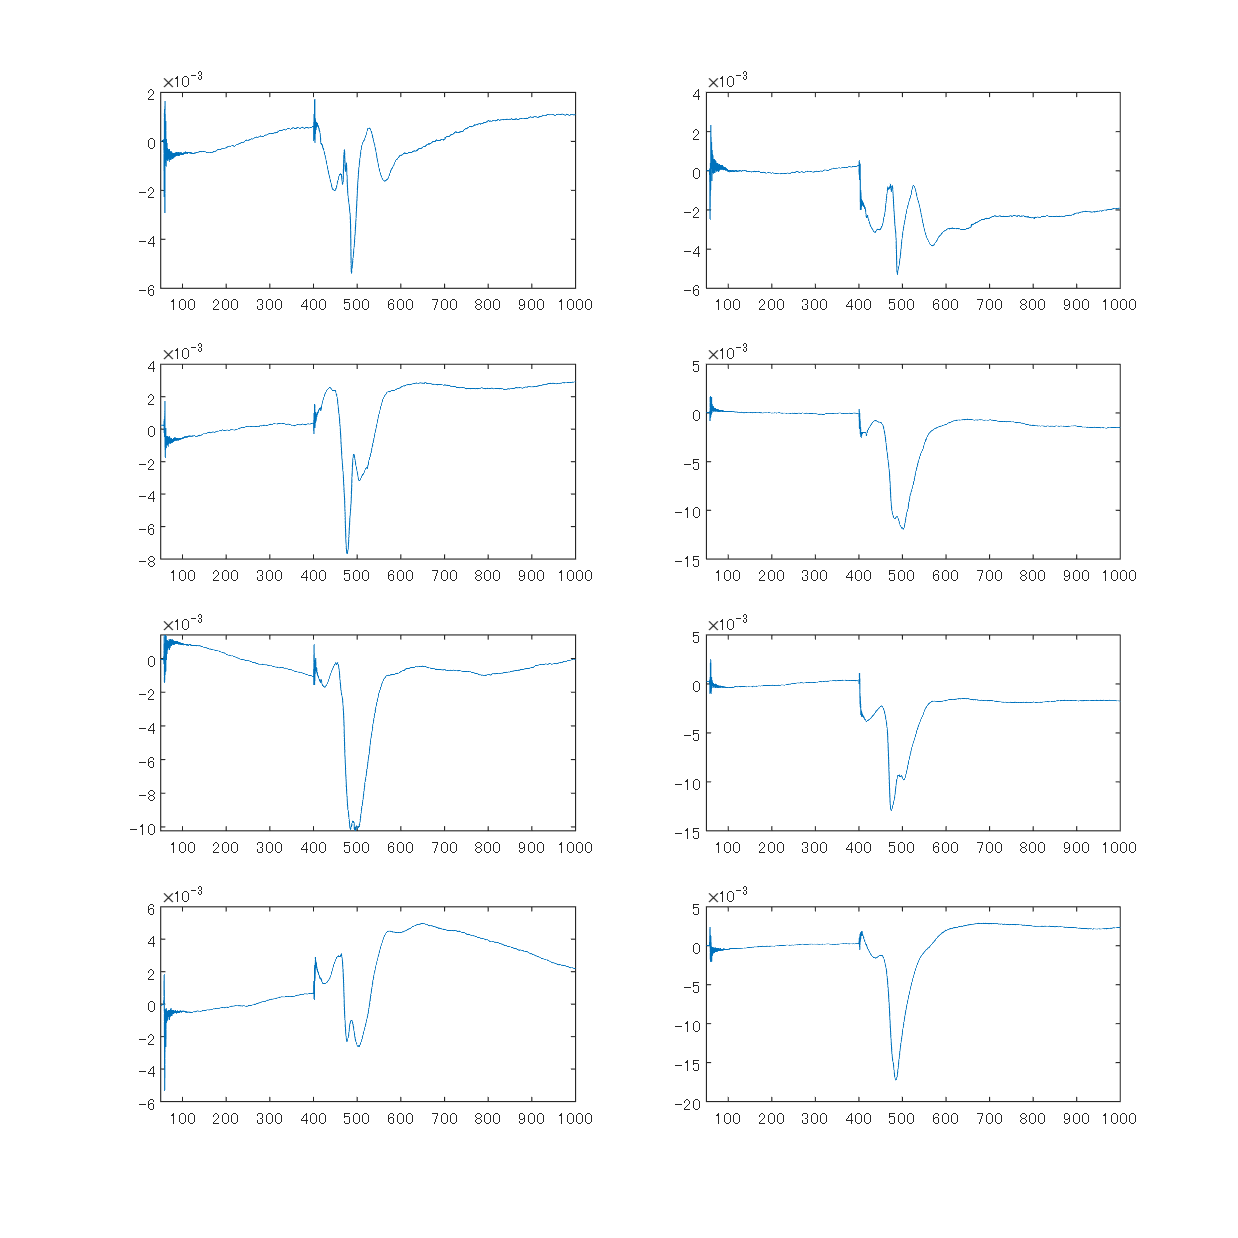


%放電前時間でオフセットを引いてみる


Bz = zeros(length(time_array),8);
for i = 1:8
    index_bz = i*3-2;
    % 数値積分
    
    % 差し引く
    Bz(:,i) = B(:,index_bz) - Bz_TF_only(:,i);

   
    % オフセットを引いてみる


    % スタート付近での放電ノイズ(プラズマつく前のまっすぐな領域の平均を引く)
    Bz(600:10020,i) = Bz(600:10020,i) - mean(Bz(800:3990,i));
    % 400usでの放電ノイズ
    %Bz(4000:10020,i) = Bz(4000:10020,i) - mean(Bz(4000:4050,i));
    % 正負そろえる
    if i == 1 || i == 2
        Bz(:,i) = Bz(:,i)*-1;
    end
    
    subplot(4,2,i)
    plot(time_array, Bz(:,i))


    xlim([50 1000])
end

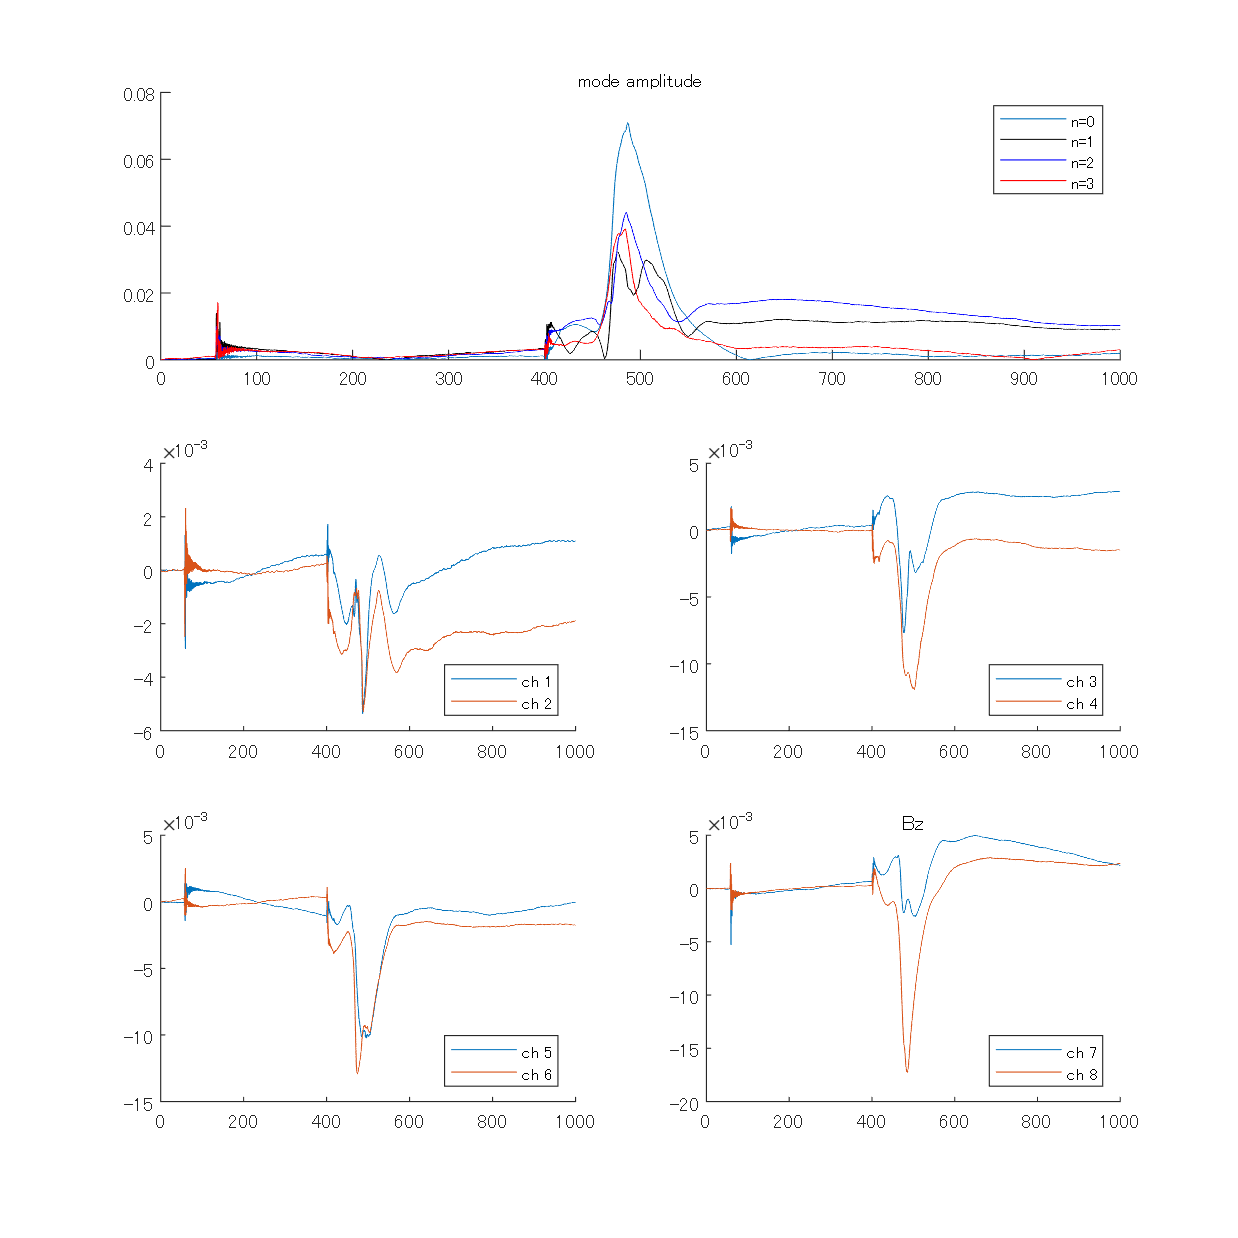

x = [0,4/24,7/24,9/24,12/24,15/24,17/24,20/24]; % non-uniform probe placement
%t = time_array(3500:6000);
t = time_array;

%measured_dBzdt = measured_dBzdt(3500:6000,:);
[n_Amp,n_Ph] = toroidal_mode(t,x,Bz); % get amplitude and phase
% calculate frequency from phase (smoothed)
%n1_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(1,:)),0.1,'loess'));
%n2_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(2,:)),0.1,'loess'));
%n3_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(3,:)),0.1,'loess'));
% *************** plotting ***************
figure('Position', [0 0 800 800]);
subplot(3,2,[1,2])
hold on
plot(t,n_Amp(1,:));
plot(t,n_Amp(2,:),'k');
plot(t,n_Amp(3,:),'b');
plot(t,n_Amp(4,:),'r');
legend('n=0','n=1','n=2','n=3');
%plot(t,smooth(n_Amp(2,:)./n_Amp(1,:),0.1,'loess'),'k');
%plot(t,smooth(n_Amp(3,:)./n_Amp(1,:),0.1,'loess'),'b');
%plot(t,smooth(n_Amp(4,:)./n_Amp(1,:),0.1,'loess'),'r');
%legend('n=1','n=2','n=3');

%legend('n=1','n=2','n=3');
%ylim([-0.1 0.3]);
xlim([t_start t_end])
title('mode amplitude')
hold off

for i = 1:4
    subplot(3,2,2+i)
    hold on
    plot(t,Bz(:,i*2-1));
    
    plot(t,Bz(:,i*2))
    xlim([t_start t_end]);
    

    legend(['ch ',num2str(i*2-1)],['ch ',num2str(i*2)],'Location','southeast')
   

    hold off
    
end
    title('Bz')
%積分信号のプロット

%xlim([t_start t_end])
%ylim([y_lowerlim y_upperlim])
%ylim([0 2000])
hold off